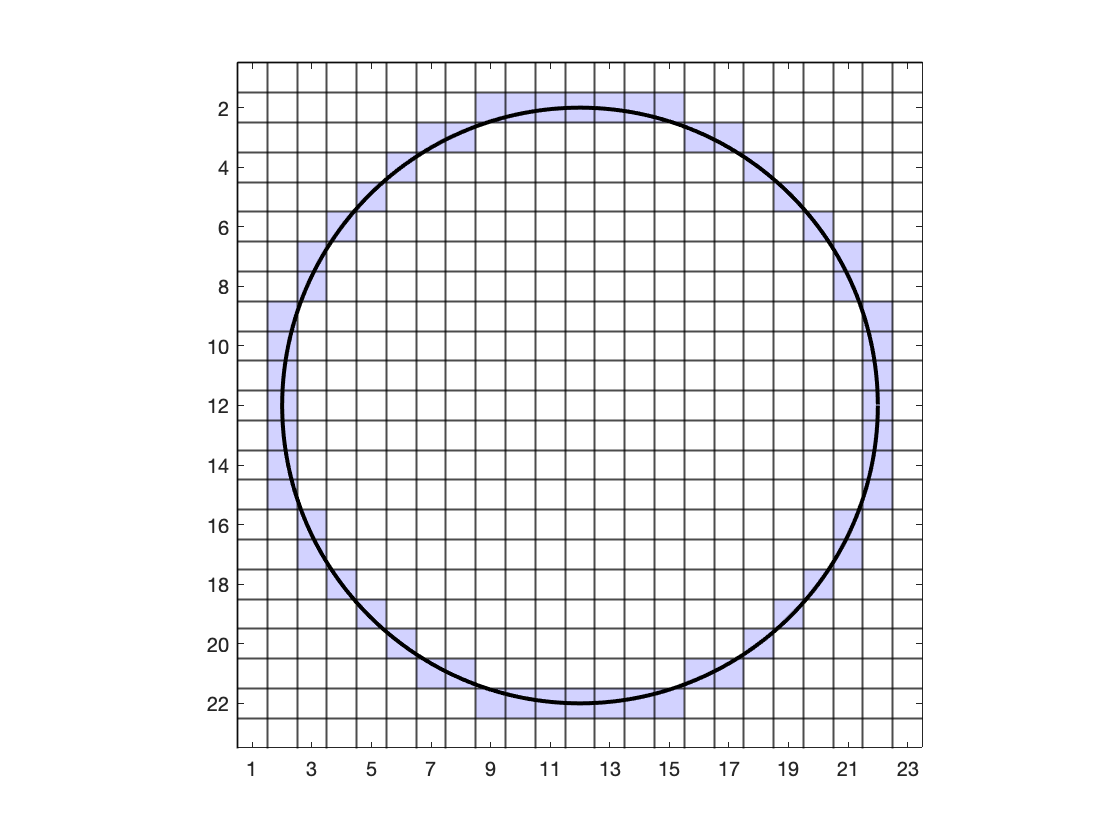

clear

% Circle co-ordinates and colour
cx = 12;
cy = 12;
r = 10;
blue = [210, 210, 255];
red = [255, 210, 210];

% Raster parameters
Nx = 23;
Ny = 23;

% Initialise raster array and calculate pixel co-ordinates
img = uint8(255 * ones(Ny, Nx, 3));

% Draw line
img = midpointcircle(img, cx, cy, r, blue);

figure
image(img)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1)
    yline(row-0.5, Color='k', LineWidth=1)
end
theta = 0 : 0.01 : 2 * pi;
x = cx + r * cos(theta);
y = cy + r * sin(theta);
plot(x, y, 'k', LineWidth=2)
hold off

xticks(1:2:Nx)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])
exportgraphics(gcf,'../images/midpoint_example.png','Resolution',300) 

function R = midpointcircle(R, cx, cy, r, colour)

x = r;
y = 0;
D = 1 - r;

while x >= y
    R(cy + y,cx + x,:) = colour;
    R(cy + y,cx - x,:) = colour;
    R(cy - y,cx + x,:) = colour;
    R(cy - y,cx - x,:) = colour;
    R(cy + x,cx + y,:) = colour;
    R(cy + x,cx - y,:) = colour;
    R(cy - x,cx + y,:) = colour;
    R(cy - x,cx - y,:) = colour;
    
    if D <= 0
        D = D + 2 * y + 3;
    else
        D = D - 2 * x + 2 * y + 5;
        x = x - 1;
    end
    y = y + 1;
end

end